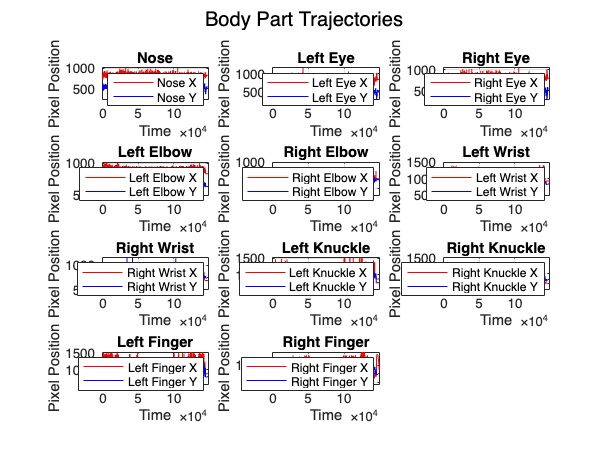

%Set the kiosk environment
%kiosk = 1 if new kiosk (Sindri, Bard)
%kiosk = 0 if old kiosk (Wotan, Frey)
kiosk = 1;

%If needed, Get the desired data segment
%Find the time frame after the NHP has entered the cage
segmentTime = 1;
pre_left = left_pre_data(segmentTime:end,:);
pre_right = right_pre_data(segmentTime:end,:);

% %If not needed, set the pre_data
% pre_left = left_pre_data;
% pre_right = right_pre_data;


%Set post-processing thresholds
conf_threshold = 0.4;
vel_threshold = 40;
z_threshold = 2.5;

%Find Optimal Time
[optimal_time_head, optimal_time_left, optimal_time_right] = find_optimal_time(pre_left,pre_right);

%Post-processing 2D pixel data
post_left = post_process(pre_left,conf_threshold, vel_threshold, z_threshold);
post_right = post_process(pre_right,conf_threshold, vel_threshold, z_threshold);

%Compare before and after of 2D Post Processing
plot_all_body_parts_subplots(post_left)

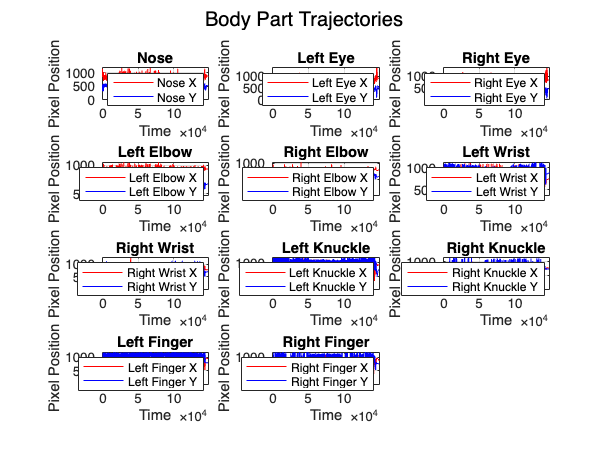

plot_all_body_parts_subplots(post_right)


%Convert data from 2D to 3D
pre_coord3D = twoD2threeD(post_left,post_right,pick_kiosk(kiosk));

%Post-processing 3D coordinate data
coord3D = post_process3D (pre_coord3D,pick_kiosk(kiosk));

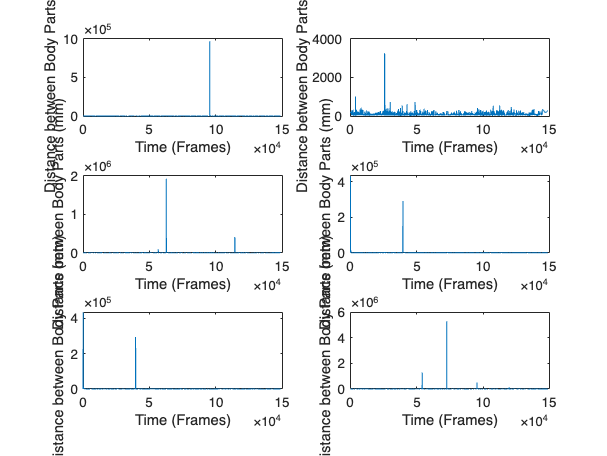


%Compare before and after of 3D Post Processing
measure_distances(pre_coord3D);

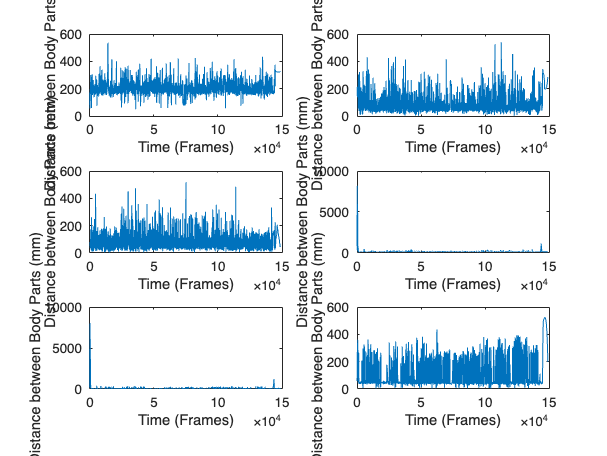

[L_Metrics, R_Metrics] = measure_distances(coord3D);

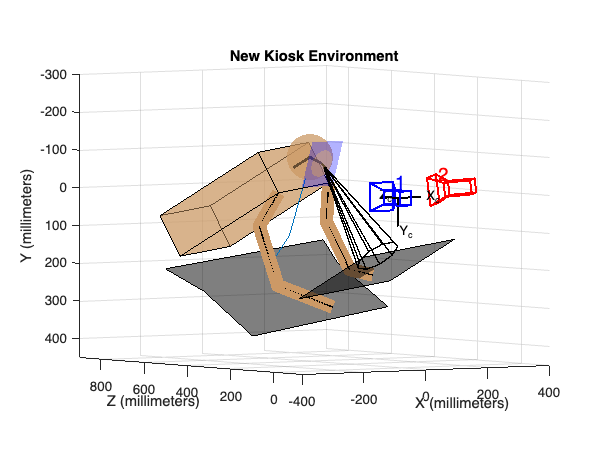


%See NHP in Kiosk at a specific time frame
time = optimal_time_head;
figure
kioskEnv = plotNHP(coord3D, time, optimal_time_head,kiosk);


%Plot a Video
%Warning: making the video is a very graphic unit demanding task
%It may take a long time
% videoName = 'trial_videoWotan.mp4';
% makeVideo(videoName, coord3D,optimal_time_head,kiosk(i))


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


function makeVideo(videoname,coord3D,optimal_time_head,kiosk)

    outputVideo = VideoWriter(videoname, 'MPEG-4');
    outputVideo.FrameRate = 30;
    open(outputVideo);
    for i = 1:length(coord3D)
        
        plotNHP(coord3D, i, optimal_time_head,kiosk)
            % Capture the current frame as an image
        frame = getframe(gcf);
        writeVideo(outputVideo, frame);
    
            % Clear the plot for the next frame
        clf;
    end
    close(outputVideo);
end

function coord3D = post_process3D (pre_coord3D, kiosk)
    
%Filter by boundary
    if kiosk == 1
        boundary = find_boundary_new(400,300);
        isOutside = isPointOutsideCuboid(boundary,pre_coord3D);
        cleanedData = replaceOutside(pre_coord3D,isOutside);

    else
        boundary = find_boundary_old(550,300);
        isOutside = isPointOutsideCuboid(boundary,pre_coord3D);
        cleanedData = replaceOutside(pre_coord3D,isOutside);
    end
%Filter by velocity
    vel_threshold = 20;

    filtered_data = filter_by_velocity3D(cleanedData, vel_threshold);
    coord3D = interpolate_data(filtered_data);

    coord3D = coord3D(1:length(pre_coord3D),:);
    coord3D(:,1:9) = pre_coord3D(:,1:9);
end



function filtered_data = filter_by_velocity3D(data, velocity_threshold)
    % Velocity-based filtering
    num_bodyparts = size(data, 2) / 3;
    filtered_data = data;
    for i = 1:num_bodyparts
        x_idx = (i-1) * 3 + 1;
        y_idx = x_idx + 1;
        z_idx = y_idx + 1;
        for t = 2:size(data, 1)
            dx = data(t, x_idx) - data(t-1, x_idx);
            dy = data(t, y_idx) - data(t-1, y_idx);
            dz = data(t, z_idx) - data(t-1, z_idx);
            velocity = sqrt(dx^2 + dy^2 + dz^2);
            if velocity > velocity_threshold
                filtered_data(t-1:t+1, x_idx:z_idx) = NaN;  % or another placeholder
            end
        end
    end
end

function cleanedData = replaceOutside(data,isOutside)
    cleanedData = data;
    for i = 1:width(data)/3
        idx = find(isOutside(:,i));
        if isempty(idx)
            continue
        end
        [~,turns] = findpeaks(data(:,i*3));
        ranges = find_consecutive_ranges(idx);

        if isempty(ranges)
            continue
        end
        row = size(ranges);
        for j = 1:row

            bottomidx = turns(max(find(turns<ranges(j,1))));
            topidx = turns(min(find(turns>ranges(j,2))));

            cleanedData(bottomidx:topidx,i*3-2:i*3) = NaN;

        end
    end
    cleanedData = interpolate_data(cleanedData);

end

function ranges = find_consecutive_ranges(numbers)    
    % Initialize the list of ranges
    ranges = [];
    
    % Initialize the start of the current range
    start_index = 1;
    
    % Loop through the numbers to find the ranges
    for i = 2:length(numbers)
        if numbers(i) ~= numbers(i-1) + 1
            % End of the current range
            end_index = i - 1;
            ranges = [ranges; numbers(start_index), numbers(end_index)];
            % Start a new range
            start_index = i;
        end
    end
    
    % Add the last range
    ranges = [ranges; numbers(start_index), numbers(end)];
end


function isOutside = isPointOutsideCuboid(vertices, data)
    minX = min(vertices(:,1));
    maxX = max(vertices(:,1));
    minY = min(vertices(:,2));
    maxY = max(vertices(:,2));
    minZ = min(vertices(:,3));
    maxZ = max(vertices(:,3));
    
    % Initialize the output array
    isOutside = false(length(data), width(data)/3);
    
    % Check if each point is outside the bounds
    for i = 1:length(data)
        for j = 1:width(data)/3
            if data(i, j*3-2) < minX || data(i, j*3-2) > maxX || ...
               data(i, j*3-1) < minY || data(i, j*3-1) > maxY || ...
               data(i, j*3) < minZ || data(i, j*3) > maxZ
                isOutside(i,j) = true;
            end
        end
    end
    % for i = 1:width(data)/3
    %     subplot(6,2,i)
    %     plot(isOutside(:,i))
    % end

end

function [L_Metrics, R_Metrics] = measure_distances(pre_coord3D)
    
    left_idx= [10:12,16:18,22:24,28:30];
    right_idx = [13:15,19:21,25:27,31:33];
    left = pre_coord3D(:,left_idx);
    right = pre_coord3D(:,right_idx);
    
    L_Metrics = zeros(length(pre_coord3D),3);
    R_Metrics = zeros(length(pre_coord3D),3);
    
    for j = 1:length((pre_coord3D))
        for i = 1:3
            L_Metrics(j,i) = distance_between_points(left(j,i*3-2:i*3),left(j,(i+1)*3-2:(i+1)*3));
            R_Metrics(j,i) = distance_between_points(right(j,i*3-2:i*3),right(j,(i+1)*3-2:(i+1)*3));
        end
    end
    figure

    for i = 1:3
        subplot(3,2,i)
        plot(L_Metrics(:,i))
        xlabel('Time (Frames)');
        ylabel('Distance between Body Parts (mm)');

        subplot(3,2,i+3)
        plot(R_Metrics(:,i))
        xlabel('Time (Frames)');
        ylabel('Distance between Body Parts (mm)');
    end

end

function distance = distance_between_points(point1, point2)
    distance = sqrt(sum((point1 - point2).^2));
end



function cuboidVertices = find_boundary_old(H,w)   

    baseVertices = [-117.9729  362.0894  379.8169
  422.0182  365.2010  379.8169
  422.7120  244.7897  587.4238
 -117.2790  241.6780  587.4238];
    baseVertices = expand_width(baseVertices,w);

    % Calculate two vectors on the bottom rectangle
    v1 = baseVertices(2, :) - baseVertices(1, :);
    v2 = baseVertices(4, :) - baseVertices(1, :);
    
    % Calculate the normal vector of the bottom rectangle
    normal = cross(v1, v2);
    normal = normal / norm(normal); % Normalize the vector
    
    
    % Calculate the top vertices by translating the base vertices along the normal vector
    topVertices = baseVertices + H * normal;
    
    % Combine the vertices for the cuboid
    cuboidVertices = [baseVertices; topVertices];   
end

function cuboidVertices = find_boundary_new(H,w)  

    screenVertices = [ -142.6699  274.0098  251.0372
  265.0828  245.7701  413.9489
  335.8716  129.0681  216.5418
  -71.8811  157.3077   53.6300];


    screenVertices = expand_width(screenVertices,w);
    screenVertices = expand_length(screenVertices,w);

    %Calculate the normal vector of the base plane
    v1 = screenVertices(2, :) - screenVertices(1, :);
    v2 = screenVertices(3, :) - screenVertices(1, :);
    normal = cross(v1, v2);
    normal = normal / norm(normal);  % Normalize the vector
    
    % Calculate the top vertices by translating the base vertices along the normal vector
    topVertices = screenVertices - H * normal;
    
    % Combine the vertices for the cuboid
    cuboidVertices = [screenVertices; topVertices];
end
function expanded_vertices = expand_width(vertices, w)
    % Calculate the midpoints of the edges to determine width direction
    mid1 = (vertices(1,:) + vertices(2,:)) / 2;
    mid2 = (vertices(3,:) + vertices(4,:)) / 2;
    
    % Calculate the width direction vector
    width_dir = mid2 - mid1;
    width_dir = width_dir / norm(width_dir); % Normalize the width direction vector
    
    % Expand the vertices in the width direction
    expanded_vertices = vertices;
    expanded_vertices(1,:) = vertices(1,:) - w * width_dir / 2;
    expanded_vertices(2,:) = vertices(2,:) - w * width_dir / 2;
    expanded_vertices(3,:) = vertices(3,:) + w * width_dir / 2;
    expanded_vertices(4,:) = vertices(4,:) + w * width_dir / 2;
end
function expanded_vertices = expand_length(vertices, w)
% Calculate the midpoints of the edges to determine length direction
    mid1 = (vertices(1,:) + vertices(4,:)) / 2;
    mid2 = (vertices(2,:) + vertices(3,:)) / 2;
    
    % Calculate the length direction vector
    length_dir = mid2 - mid1;
    length_dir = length_dir / norm(length_dir); % Normalize the length direction vector
    
    % Expand the vertices in the length direction
    expanded_vertices = vertices;
    expanded_vertices(1,:) = vertices(1,:) - w * length_dir / 2;
    expanded_vertices(4,:) = vertices(4,:) - w * length_dir / 2;
    expanded_vertices(2,:) = vertices(2,:) + w * length_dir / 2;
    expanded_vertices(3,:) = vertices(3,:) + w * length_dir / 2;
end


function [optimal_time_head, optimal_time_left, optimal_time_right] = find_optimal_time(pre_left,pre_right)
    %Find optimal time of a body part
    %Nose, Left Eye, Right Eye = 1:3
    %Left_Elbow, Right_Elbow = 4:5
    %Left_Wrist, Right_Wrist = 6:7
    %Left_Hand, Right_Hand = 8:9
    %Left_Finger, Right_Finger = 10:11
    optimal_time_head = find_optimal_time_point(pre_left,pre_right,1:3);
    optimal_time_left = find_optimal_time_point(pre_left,pre_right,4:2:10);
    optimal_time_right = find_optimal_time_point(pre_left,pre_right,5:2:11);

end

function filtered_data = filter_by_confidence(data, confidence_threshold)
    num_bodyparts = size(data, 2) / 3;
    filtered_data = data;
    for i = 1:num_bodyparts
        conf_idx = i * 3;
        low_confidence_idx = data(:, conf_idx) < confidence_threshold;
        filtered_data(low_confidence_idx, (i-1)*3+1:i*3) = NaN;  % or another placeholder
    end
end

function interpolated_data = interpolate_data(data)
    for i = 1:width(data)
        narrowed_data = data(:,i);
        valid_indices = find(~isnan(narrowed_data));
        if length(valid_indices) > 49
            first50 = mean(narrowed_data(valid_indices(1:50)));
            last50 = mean(narrowed_data(valid_indices(end-49:end)));
        else
            first50 = mean(narrowed_data(valid_indices));
            last50 = mean(narrowed_data(valid_indices));
        end
        if isnan(narrowed_data(1))
            narrowed_data(1) = first50;
        end
        if isnan(narrowed_data(end))
            narrowed_data(end) = last50;
        end
        data(:,i) = narrowed_data;

    end
    for i = 1:size(data, 2)
        nan_idx = isnan(data(:, i));
        zero_idx = data(:, i) == 0;
        if any(nan_idx)
            data(nan_idx, i) = interp1(find(~nan_idx), data(~nan_idx, i), find(nan_idx), 'pchip');
        end
        if any(zero_idx)
            data(zero_idx, i) = interp1(find(~zero_idx), data(~zero_idx, i), find(zero_idx), 'pchip');
        end
    end
    interpolated_data = data;
end

function filtered_data = remove_outliers(data, z_threshold)
    % Outlier detection using z-score
    filtered_data = data;
    for i = 1:size(data, 2)
        z_scores = zscore(data(:, i));
        outliers_idx = abs(z_scores) > z_threshold;
        filtered_data(outliers_idx, i) = NaN;  % or another placeholder
    end
end

function filtered_data = filter_by_velocity(data, velocity_threshold)
    % Velocity-based filtering
    num_bodyparts = size(data, 2) / 3;
    filtered_data = data;
    for i = 1:num_bodyparts
        x_idx = (i-1) * 3 + 1;
        y_idx = x_idx + 1;
        for t = 2:size(data, 1)
            dx = data(t, x_idx) - data(t-1, x_idx);
            dy = data(t, y_idx) - data(t-1, y_idx);
            velocity = sqrt(dx^2 + dy^2);
            if velocity > velocity_threshold
                filtered_data(t, x_idx:y_idx) = NaN;  % or another placeholder
            end
        end
    end
end

function processed_data = post_process(data, conf_threshold, vel_threshold, z_threshold)
    % Step 1: Filter by confidence
    data = filter_by_confidence(data, conf_threshold);
    

    % Step 2: Remove outliers
    data = remove_outliers(data, z_threshold);
    
    % Step 3: Interpolate data
    data = interpolate_data(data);

    % Step 4: Filter by velocity
    data = filter_by_velocity(data, vel_threshold);
    processed_data = interpolate_data(data);
end

function plot_all_body_parts_subplots(data)
    % Check if the input data has the correct dimensions
    [~, num_features] = size(data);
    if mod(num_features, 3) ~= 0 || num_features ~= 33
        error('Input data must be an x by 33 matrix.');
    end
    
    num_bodyparts = num_features / 3;

    % Determine the number of rows and columns for subplots
    num_cols = 3; % Arbitrary choice for layout, you can adjust
    num_rows = ceil(num_bodyparts / num_cols);

    figure;
    for i = 1:num_bodyparts
        x_idx = (i-1) * 3 + 1;
        y_idx = x_idx + 1;

        body_part = ["Nose","Left Eye","Right Eye","Left Elbow","Right Elbow","Left Wrist","Right Wrist","Left Knuckle","Right Knuckle","Left Finger","Right Finger"];

        subplot(num_rows, num_cols, i);
        plot(data(:, x_idx), 'r', 'DisplayName', body_part(i) + ' X');
        hold on;
        plot(data(:, y_idx), 'b', 'DisplayName', body_part(i) + ' Y');
        hold off;

        xlabel('Time');
        ylabel('Pixel Position');
        title(body_part(i));
        legend show;
        grid on;
    end

    % Adjust the figure layout
    sgtitle('Body Part Trajectories');
end

function pre_coord3D = twoD2threeD (left,right, kiosk)
    pre_coord3D = zeros(size(left));
    for ii = 1:length(left)
        for jj = 1:3:width(left)
            if sum(isnan(left(ii,jj:jj+1))) + sum(isnan(right(ii,jj:jj+1))) ~= 0
                continue
            else
                pre_coord3D(ii,jj:jj+2) = triangulate(left(ii,jj:jj+1),right(ii,jj:jj+1),kiosk);
            end
        end
    end
end

function optimal_time_point = find_optimal_time_point(left, right,bodyparts)
    % Check if the number of rows in both matrices are the same
    if size(left, 1) ~= size(right, 1)
        error('Left and right matrices must have the same number of rows (time points).');
    end

    % Initialize the total probabilities for each time point
    total_probabilities = zeros(size(left, 1), 1);

    % Sum the probabilities for each time point in both matrices
    for i = bodyparts
        left_probabilities = left(:, (i-1)*3 + 3);
        left_probabilities(isnan(left_probabilities)) = 0;
        right_probabilities = right(:, (i-1)*3 + 3);
        right_probabilities(isnan(right_probabilities)) = 0;
        total_probabilities = total_probabilities + left_probabilities + right_probabilities;
    end

    % Find the time point with the highest total probability
    [~, optimal_time_point] = max(total_probabilities);
end

function params = pick_kiosk (whichKiosk)
    %Old = 0, New = 1
    if whichKiosk
        load ('NewKioskCalibration.mat')
        
        
        params = calibrationSession.CameraParameters;
    else
        load('OldKioskCalibration.mat')
        
        params = calibrationSession.CameraParameters;
    end
end
function kioskEnv = plotNHP(coord3D, time, optimal_time_head,kiosk)

    if kiosk == 1
        figure
        [kioskEnv,~] = physicalEnvironment(1);
        hold on
        [head_center, R, ~] =plot_head(coord3D, time,optimal_time_head);
        shoulder = plot_torso_new(head_center, R, kioskEnv);
        % boundary = find_boundary_new_plot(kioskEnv,100,0);
        plot_arms_new(coord3D,time,shoulder)
        xlim([-400 400])
        zlim([-300 450])
        ylim([-130 900])
        view(-35,3)
        title('New Kiosk Environment')
        
        hold off
    else
        figure
        [kioskEnv,~] = physicalEnvironment(0);
        hold on
        [head_center, R, ~] =plot_head(coord3D, time,optimal_time_head);
        shoulder = plot_torso_old(head_center, R, kioskEnv);
        plot_arms_old(coord3D,time,shoulder);
        % boundary = find_boundary_old_plot(base_vertices,550,300);
        % plot_cuboid(boundary)
        xlim([-150 500])
        zlim([-200 500])
        ylim([-30 900])
        view(-35,2)
        title('Old Kiosk Environment')

        hold off
    end

end

function plot_cuboid(vertices)
    % Ensure the vertices are provided as an 8x3 matrix
    if size(vertices, 1) ~= 8 || size(vertices, 2) ~= 3
        error('Vertices should be an 8x3 matrix.');
    end
    
    % Define the faces of the cuboid using the vertex indices
    faces = [
        1, 2, 3, 4;  % Bottom face
        5, 6, 7, 8;  % Top face
        1, 2, 6, 5;  % Front face
        2, 3, 7, 6;  % Right face
        3, 4, 8, 7;  % Back face
        4, 1, 5, 8;  % Left face
    ];
    
    
    transformed_vertices = [vertices(:,1) vertices(:,3) vertices(:,2)];
    % Plot the cuboid using the patch function
    patch('Vertices', transformed_vertices, 'Faces', faces, 'FaceColor', 'cyan', 'FaceAlpha', 0.3, 'EdgeColor', 'blue', 'LineWidth', 1.5);
end

function cuboidVertices = find_boundary_old_plot(baseVertices, H,w)   
    baseVertices = expand_width(baseVertices,w);

    % Calculate two vectors on the bottom rectangle
    v1 = baseVertices(2, :) - baseVertices(1, :);
    v2 = baseVertices(4, :) - baseVertices(1, :);
    
    % Calculate the normal vector of the bottom rectangle
    normal = cross(v1, v2);
    normal = normal / norm(normal); % Normalize the vector
    
    
    % Calculate the top vertices by translating the base vertices along the normal vector
    topVertices = baseVertices + H * normal;
    
    % Combine the vertices for the cuboid
    cuboidVertices = [baseVertices; topVertices];   
end

function cuboidVertices = find_boundary_new_plot(screenVertices, H,w)   
    screenVertices = expand_width(screenVertices,w);
    screenVertices = expand_length(screenVertices,w);
    % Extract the coordinates of the base vertices
    x = screenVertices(:, 1);
    y = screenVertices(:, 2);
    z = screenVertices(:, 3);

    %Calculate the normal vector of the base plane
    v1 = screenVertices(2, :) - screenVertices(1, :);
    v2 = screenVertices(3, :) - screenVertices(1, :);
    normal = cross(v1, v2);
    normal = normal / norm(normal);  % Normalize the vector
    
    % Calculate the top vertices by translating the base vertices along the normal vector
    topVertices = screenVertices - H * normal;
    
    % Combine the vertices for the cuboid
    cuboidVertices = [screenVertices; topVertices];
    plot_cuboid(cuboidVertices)
end

function plot_arms_old(coord3D, time, shoulders)
    leftxs = [shoulders(2,1), coord3D(time,10:6:end-6)];
    leftys = [shoulders(2,2), coord3D(time,11:6:end-6)];
    leftzs = [shoulders(2,3), coord3D(time,12:6:end-6)];

    rightxs = [shoulders(1,1), coord3D(time,13:6:end-6)];
    rightys = [shoulders(1,2), coord3D(time,14:6:end-6)];
    rightzs = [shoulders(1,3), coord3D(time,15:6:end-6)];

    plot3(leftxs,leftzs,leftys,'LineWidth', 10,'Color',[0.8 0.6 0.4]);
    plot3(rightxs,rightzs,rightys,'LineWidth', 10,'Color',[0.8 0.6 0.4]);
    plot3(leftxs,leftzs,leftys,'LineWidth', 1,'Color','k');
    plot3(rightxs,rightzs,rightys,'LineWidth', 1,'Color','k');

end


function plot_arms_new(coord3D, time, shoulders)
    leftxs = [shoulders(1,1), coord3D(time,10:6:end-6)];
    leftys = [shoulders(1,2), coord3D(time,11:6:end-6)];
    leftzs = [shoulders(1,3), coord3D(time,12:6:end-6)];

    rightxs = [shoulders(2,1), coord3D(time,13:6:end-6)];
    rightys = [shoulders(2,2), coord3D(time,14:6:end-6)];
    rightzs = [shoulders(2,3), coord3D(time,15:6:end-6)];

    plot3(leftxs,leftzs,leftys, 'LineWidth', 10,'Color',[0.8 0.6 0.4]);
    plot3(rightxs,rightzs,rightys,'LineWidth', 10,'Color',[0.8 0.6 0.4]);
    plot3(leftxs,leftzs,leftys,'LineWidth', 1,'Color','k');
    plot3(rightxs,rightzs,rightys,'LineWidth', 1,'Color','k');

end

function shoulder = plot_torso_old(head_center, R, screen_vertices)
    % Calculate the direction vector for the vertical edges of the screen
    direction_vertical = screen_vertices(4, :) - screen_vertices(1, :);
    direction_vertical = direction_vertical / norm(direction_vertical); % Normalize the direction vector

    % Calculate the direction vector for the horizontal edges of the screen
    direction_horizontal = screen_vertices(2, :) - screen_vertices(1, :);
    direction_horizontal = direction_horizontal / norm(direction_horizontal); % Normalize the direction vector

    % Calculate the endpoint
    end_point = head_center + R * direction_vertical;

    % Define the top rectangle vertices relative to the end_point
    half_length = 2*R;
    half_width = R;
    vertices_top_face = [
        -half_length, -half_width, 0;
        half_length, -half_width, 0;
        half_length, half_width, 0;
        -half_length, half_width, 0;
    ];

    % Transform vertices to be aligned with the direction vectors
    up = cross(direction_horizontal, direction_vertical); % Up direction perpendicular to screen plane
    R_matrix = [direction_horizontal; up; direction_vertical]';
    vertices_top_face = (R_matrix * vertices_top_face')';
    vertices_top_face = vertices_top_face + end_point; % Translate vertices to end_point

    % Calculate the bottom rectangle vertices in the opposite direction
    vertices_bottom_face = vertices_top_face + 6 * R * direction_vertical;

    % Combine top and bottom face vertices
    vertices = [vertices_top_face; vertices_bottom_face];
    shoulder = vertices(1:2, :);

    % Define the cuboid faces
    faces = [
        1, 2, 3, 4; % Top face
        5, 6, 7, 8; % Bottom face
        1, 2, 6, 5; % Front face
        2, 3, 7, 6; % Right face
        3, 4, 8, 7; % Back face
        4, 1, 5, 8; % Left face
    ];

    
    % Plot the head center and endpoint
    % plot3(head_center(1), head_center(2), head_center(3), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
    % plot3(end_point(1), end_point(2), end_point(3), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
    % 
    % Plot the line between head center and endpoint
    plot3([head_center(1), end_point(1)], [head_center(3), end_point(3)], [head_center(2), end_point(2)], 'k-', 'LineWidth', 2);

    % Transform vertices for plotting
    vertices_transformed = [vertices(:,1), vertices(:,3), vertices(:,2)];
    
    % Plot the cuboid
    patch('Vertices', vertices_transformed, 'Faces', faces, 'FaceColor', [0.8 0.6 0.4], 'FaceAlpha', 0.5);
end
function shoulder = plot_torso_new(head_center, R, screen_vertices)
    % Calculate the direction vector for the vertical edges of the screen
    direction_vertical = screen_vertices(4, :) - screen_vertices(1, :);
    direction_vertical = direction_vertical / norm(direction_vertical); % Normalize the direction vector

    % Calculate the direction vector for the horizontal edges of the screen
    direction_horizontal = screen_vertices(2, :) - screen_vertices(1, :);
    direction_horizontal = direction_horizontal / norm(direction_horizontal); % Normalize the direction vector

    % Calculate the endpoint
    end_point = head_center - R * direction_vertical;

    % Define the top rectangle vertices relative to the end_point
    half_length = 2*R;
    half_width = R;
    vertices_top_face = [
        -half_length, -half_width, 0;
        half_length, -half_width, 0;
        half_length, half_width, 0;
        -half_length, half_width, 0;
    ];

    % Transform vertices to be aligned with the direction vectors
    up = cross(direction_horizontal, direction_vertical); % Up direction perpendicular to screen plane
    R_matrix = [direction_horizontal; up; direction_vertical]';
    vertices_top_face = (R_matrix * vertices_top_face')';
    vertices_top_face = vertices_top_face + end_point; % Translate vertices to end_point

    % Calculate the bottom rectangle vertices in the opposite direction
    vertices_bottom_face = vertices_top_face - 6 * R * direction_vertical;

    % Combine top and bottom face vertices
    vertices = [vertices_top_face; vertices_bottom_face];
    shoulder = vertices(3:4, :);

    % Define the cuboid faces
    faces = [
        1, 2, 3, 4; % Top face
        5, 6, 7, 8; % Bottom face
        1, 2, 6, 5; % Front face
        2, 3, 7, 6; % Right face
        3, 4, 8, 7; % Back face
        4, 1, 5, 8; % Left face
    ];

    
    % Plot the head center and endpoint
    % plot3(head_center(1), head_center(2), head_center(3), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
    % plot3(end_point(1), end_point(2), end_point(3), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
    % 
    % Plot the line between head center and endpoint
    plot3([head_center(1), end_point(1)], [head_center(3), end_point(3)], [head_center(2), end_point(2)], 'k-', 'LineWidth', 2);

    % Transform vertices for plotting
    vertices_transformed = [vertices(:,1), vertices(:,3), vertices(:,2)];
    
    % Plot the cuboid
    patch('Vertices', vertices_transformed, 'Faces', faces, 'FaceColor', [0.8 0.6 0.4], 'FaceAlpha', 0.5);
end
function [head_center,R, centroid] = plot_head(data,time,optimal_time)

    % Plotting for visualization

    interpupillary_distance = standard(data,optimal_time);

    R = 1.3*interpupillary_distance;

    [plane_normal, plane_point] = find_plane(data, time, R);

    nose = data(time, 1:3);
    left_eye = data(time, 4:6);
    right_eye = data(time, 7:9);

    centroid = (left_eye + right_eye + nose) / 3;

    head_center = find_head_center(centroid, plane_normal, interpupillary_distance);

    [x, y, z] = sphere(50);
    x = R * x;
    y = R * y;
    z = R * z;

    % Translate the sphere to the calculated center
    x = x + head_center(1);
    y = y + head_center(2);
    z = z + head_center(3);

    plot3([centroid(1) head_center(1)], [centroid(3) head_center(3)], [centroid(2) head_center(2)], 'k-', 'LineWidth', 2);

    surf(x, z, y, 'FaceAlpha', 0.5, 'EdgeColor', 'none', 'FaceColor', [0.8 0.6 0.4]);

    end1 = find_end_point(centroid, 5*R, plane_normal,60,left_eye,right_eye);
    plot_cone(centroid,end1,R);

    compute_distance_to_plane(plane_normal,plane_point,head_center);
end

function [end1,end2] = find_end_point(apex, height, plane_normal,degree,p1,p2)
    % Normalize the plane normal vector
    plane_normal = plane_normal / norm(plane_normal);
    
        % Find the direction vector of the line formed by p1 and p2
    line_dir = p2 - p1;
    line_dir = line_dir / norm(line_dir);
    
    % Ensure the line direction is perpendicular to the plane normal
    perp1 = cross(plane_normal, line_dir);
    perp1 = perp1 / norm(perp1);
    
    % Generate a second perpendicular vector to form a plane
    perp2 = cross(plane_normal, perp1);
    perp2 = perp2 / norm(perp2);
    
    % % Generate a grid of points for the plane centered at the apex
    % grid_size = 10;  % Define the size of the grid
    % [u, v] = meshgrid(-grid_size:grid_size, -grid_size:grid_size);
    % x = apex(1) + u * perp1(1) + v * perp2(1);
    % y = apex(2) + u * perp1(2) + v * perp2(2);
    % z = apex(3) + u * perp1(3) + v * perp2(3);
    % 
    % % Plot the plane with apex as its center
    % surf(x, z, y, 'FaceAlpha', 0.5, 'EdgeColor', 'none');
    
    % Find the end_point
    % end_point = apex + height * plane_normal;
    
    % % Plot the line between apex and end_point
    % plot3([apex(1), end_point(1)], [apex(3), end_point(3)], [apex(2), end_point(2)], 'r', 'LineWidth', 3);
    
    % Create a circle in the plane defined by perp1 and plane_normal
    theta = linspace(0, deg2rad(degree), 100);
    circle1_x = apex(1) + height * (cos(theta) * perp1(1) + sin(theta) * plane_normal(1));
    circle1_y = apex(2) + height * (cos(theta) * perp1(2) + sin(theta) * plane_normal(2));
    circle1_z = apex(3) + height * (cos(theta) * perp1(3) + sin(theta) * plane_normal(3));
    % plot3(circle1_x, circle1_z, circle1_y, 'b', 'LineWidth', 2);
    
    % Create a circle in the plane defined by perp2 and plane_normal
    circle2_x = apex(1) + height * (cos(theta) * perp2(1) + sin(theta) * plane_normal(1));
    circle2_y = apex(2) + height * (cos(theta) * perp2(2) + sin(theta) * plane_normal(2));
    circle2_z = apex(3) + height * (cos(theta) * perp2(3) + sin(theta) * plane_normal(3));
    % plot3(circle2_x, circle2_z, circle2_y, 'g', 'LineWidth', 2);

    end1 = [circle1_x(end),circle1_y(end),circle1_z(end)];
    end2 = [circle2_x(end),circle2_y(end),circle2_z(end)];
end
function plot_cone(apex, end_point, radius)
    % Calculate the direction vector from apex to end_point
    direction = end_point - apex;
    height = norm(direction);
    direction = direction / height;  % Normalize the direction vector
    
    % Find two perpendicular vectors to the direction
    if direction(1) == 0 && direction(2) == 0
        perp1 = [1, 0, 0];
    else
        perp1 = [-direction(2), direction(1), 0];
        perp1 = perp1 / norm(perp1);
    end
    
    perp2 = cross(direction, perp1);
    
    % Generate the circle at the base of the cone
    theta = linspace(0, 2*pi, 10);
    circle_x = end_point(1) + radius * (cos(theta) * perp1(1) + sin(theta) * perp2(1));
    circle_y = end_point(2) + radius * (cos(theta) * perp1(2) + sin(theta) * perp2(2));
    circle_z = end_point(3) + radius * (cos(theta) * perp1(3) + sin(theta) * perp2(3));
    
    % Plot the base circle
    plot3(circle_x, circle_z, circle_y, 'k', 'LineWidth', 1);
    
    % Plot the lines from apex to the base circle
    for i = 1:length(theta)
        plot3([apex(1), circle_x(i)], [apex(3), circle_z(i)], [apex(2), circle_y(i)], 'k', 'LineWidth', 1);
    end
    
    % % Plot the line between apex and end_point
    % plot3([apex(1), end_point(1)], [apex(3), end_point(3)], [apex(2), end_point(2)], 'r', 'LineWidth', 3);

end

function point = find_head_center(centroid, plane_normal, d)
    % Normalize the plane normal vector
    plane_normal = plane_normal / norm(plane_normal);

    % Calculate the point that is at a distance d from the centroid along the plane normal
    point = centroid - d * plane_normal;
end

function distance = compute_distance_to_plane(plane_normal, plane_point, sphere_center)
    % Normalize the plane normal vector
    plane_normal = plane_normal / norm(plane_normal);

    % Calculate the distance from the sphere center to the plane
    % Plane equation: ax + by + cz + d = 0
    % d = -dot(plane_normal, plane_point)
    d = -dot(plane_normal, plane_point);

    % Calculate the distance using the point-to-plane distance formula
    distance = abs(dot(plane_normal, sphere_center) + d);
    % 
    % % Display the result
    % disp('Distance between the plane and the center of the sphere:');
    % disp(distance);
end

function interpupillary_distance = standard(data,time)
    left_eye = data(time,4:6);
    right_eye = data(time,7:9);

    interpupillary_distance = norm(left_eye - right_eye);
end

function [plane_normal, plane_point] = find_plane(data, time, R)
    % Extract the coordinates of the points
    nose = data(time, 1:3);
    left_eye = data(time, 4:6);
    right_eye = data(time, 7:9);
    
    % Calculate the normal vector of the plane defined by the three points
    v1 = left_eye - nose;
    v2 = right_eye - nose;
    plane_normal = cross(v1, v2);
    plane_normal = plane_normal / norm(plane_normal); % Normalize the plane normal vector

    centroid = (nose + left_eye + right_eye) / 3;
    plane_point = centroid;


    [xx, yy] = meshgrid(linspace(-R, R, 50), linspace(-R, R, 50));
    zz = (-plane_normal(1) * (xx - centroid(1)) - plane_normal(2) * (yy - centroid(2)) - ...
          dot(plane_normal, centroid)) / plane_normal(3) + centroid(3);

    % Translate the plane to be centered around the centroid
    xx = xx + centroid(1);
    yy = yy + centroid(2);
    zz = zz + centroid(3);

    % Plot the plane
    surf(xx, zz, yy, 'FaceAlpha', 0.3, 'EdgeColor', 'none', 'FaceColor', 'b');
    % plot3(nose(1), nose(3), nose(2), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    % plot3(left_eye(1), left_eye(3), left_eye(2), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
    % plot3(right_eye(1), right_eye(3), right_eye(2), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
    % plot3(centroid(1), centroid(3), centroid(2), 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'k');
end

function [kioskEnv, base_vertices] = physicalEnvironment(newKiosk)
    % Loc =  {"TubTipX", "TubTipY","TubeCurveX","TubeCurveY","TubeBaseX",'TubeBaseY','L_HandlebarX','L_HandlebarY','R_HandlebarX','R_HandlebarY','LBscreenX','LBscreenY','RBscreenX','RBscreenY'};
    KioskOldRight = [698 612 624	787 628 856	681 972	316 1068 1075 1184 1070 830 477 780];
    
    KioskNewRight = [822 538 841 683 859 744 525 896 1235 1062 1160 811 1189 734 645 676 636 746 1260 800];
    
    KioskOldLeft = [995	600	1057 773 1040 852	994 959	599 1167 1351 1059 1200 716 604 812];
    
    KioskNewLeft = [805 561 796 718 782 770 392 1153 1099 878 991 747 981 685 432 782 470 863 1097 708];
    
    
    load('NewKioskCalibration.mat')
    
    
    stereoParamsNew = calibrationSession.CameraParameters;
    
    load('OldKioskCalibration.mat')
    
    stereoParamsOld = calibrationSession.CameraParameters;
    
    leftNew = reshape(KioskNewLeft,2,10)';
    rightNew = reshape(KioskNewRight,2,10)';
    
    leftOld = reshape(KioskOldLeft,2,8)';
    rightOld = reshape(KioskOldRight,2,8)';


    if newKiosk

        coord3D = triangulate(leftNew,rightNew,stereoParamsNew);

        plot3(coord3D(1:3,1),coord3D(1:3,3),coord3D(1:3,2))
        hold on
        base_vertices = plot_base_new(coord3D(4:9,1),coord3D(4:9,3),coord3D(4:9,2));
        screen_vertices = plot_screen_new(coord3D(6,:),coord3D(10,:),coord3D(1,:),coord3D(4,:),coord3D(5,:));
        showExtrinsics_noBoard(stereoParamsNew)

        compute_distance(coord3D(5,:),coord3D(6,:));
        
        hold off 
    else 
        
        coord3D = triangulate(leftOld,rightOld,stereoParamsOld);
        
        plot3(coord3D(1:4,1),coord3D(1:4,3),coord3D(1:4,2))
        hold on
        screen_vertices = plot_screen_old(coord3D(1,:),coord3D(2,:));
        base_vertices = plot_base_old(coord3D(3,:),coord3D(4,:));
        showExtrinsics_noBoard(stereoParamsOld)
        hold off


    end

    kioskEnv = screen_vertices;
end
function new_vertices = plot_screen_new(p1, p2, p3, p4, p5)
    L = 440; % Length of the rectangle
    W = 240; % Width of the rectangle
    d1 = 45;
    d = 310;


    % Calculate the direction vector from p1 to p2 for the first alignment
    direction1 = p2 - p1;
    direction1 = direction1 / norm(direction1); % Normalize the direction vector

    % Calculate the direction vector from p4 to p5 for the second alignment
    direction2 = p5 - p4;
    direction2 = direction2 / norm(direction2); % Normalize the direction vector

    % Define the initial rectangle vertices relative to its centroid (p3)
    half_length = L / 2;
    half_width = W / 2;
    vertices = [
        -half_length, -half_width, 0;
        half_length, -half_width, 0;
        half_length, half_width, 0;
        -half_length, half_width, 0;
    ];

    % Initial transformation matrix to align the length of the rectangle with direction1
    up = [0, 0, 1];
    if abs(dot(up, direction1)) == 1
        up = [0, 1, 0];
    end
    right1 = cross(up, direction1);
    right1 = right1 / norm(right1); % Normalize the right vector
    up = cross(direction1, right1); % Correct up vector orthogonal to both
    R_matrix_initial = [right1; direction1; up]';
    vertices = (R_matrix_initial * vertices')';

    % Translate vertices to have p3 as the centroid
    vertices = vertices + p3;

    % Calculate the angle and axis for the second rotation to align the width with direction2
    angle_between = acos(dot(right1, direction2));
    rotation_axis = cross(right1, direction2);
    rotation_axis = rotation_axis / norm(rotation_axis); % Normalize the rotation axis

    % Construct the rotation matrix using Rodrigues' rotation formula
    K = [
        0, -rotation_axis(3), rotation_axis(2);
        rotation_axis(3), 0, -rotation_axis(1);
        -rotation_axis(2), rotation_axis(1), 0
    ];
    R = eye(3) + sin(angle_between) * K + (1 - cos(angle_between)) * (K * K);

    % Apply the rotation to align the width with direction2
    vertices = (R * (vertices - p3)')' + p3;

    % Calculate the centroid of the rectangle
    % centroid = mean(vertices);

    % Calculate the bottom edge center
    bottom_edge_center = mean(vertices(1:2, :)); % The center of the bottom edge

    % Calculate the translation vector to move p3 to be d1 units away from the bottom edge
    bottom_to_p3 = p3 - bottom_edge_center; % Vector from the bottom edge center to p3
    bottom_to_p3_length = norm(bottom_to_p3); % Distance from bottom edge center to p3

    % Calculate the required translation vector along the plane
    translation_vector = (d1 - bottom_to_p3_length) * (bottom_to_p3 / bottom_to_p3_length);

    % Translate the vertices
    new_vertices = vertices - translation_vector;
    new_vertices = translate_perpendicular(new_vertices, d);

    % Plot the rectangle
    fill3(new_vertices(:,1), new_vertices(:,3), new_vertices(:,2), 'black', 'FaceAlpha', 0.5, 'DisplayName', 'Rectangle');
end
function new_vertices = translate_perpendicular(vertices, d)
    % Calculate two vectors from the rectangle vertices to define the plane
    v1 = vertices(2, :) - vertices(1, :);
    v2 = vertices(4, :) - vertices(1, :);

    % Calculate the normal vector of the plane
    plane_normal = cross(v1, v2);
    plane_normal = plane_normal / norm(plane_normal); % Normalize the normal vector

    % Translate the rectangle by d units in the direction of the normal vector
    new_vertices = vertices + d * plane_normal;
end
function base_vertices = plot_base_new(xs,ys,zs)  
    points = [xs, ys, zs];
    % Calculate the centroid of the points
    centroid = mean(points);
    
    % Subtract the centroid from the points
    centered_points = points - centroid;
    
    % Compute the singular value decomposition (SVD)
    [~, ~, V] = svd(centered_points, 0);
    
    % The normal vector to the best-fit plane is given by the last column of V
    normal_vector = V(:, end);
    
    % Project the points onto the plane
    adjusted_points = points - (centered_points * normal_vector) * normal_vector';
    
    base_vertices = [adjusted_points(1:2,:); adjusted_points(5:6,:)]; 
    % Connect the points to form a shape
    fill3(adjusted_points(:, 1), adjusted_points(:, 2), adjusted_points(:, 3), 'black', 'FaceAlpha', 0.5, 'DisplayName', 'Adjusted Shape');
    
end
function base_vertices = plot_base_old(p1, p2)
    L = 540;
    W = 240;
    offset_from_bottom = 75;
    d = 35;
    % Calculate the direction vector from p1 to p2
    direction = p2 - p1;
    direction = direction / norm(direction); % Normalize the direction vector

    % Find the point on the line that is d units away from p2
    point_on_line = p2 + d * direction;

    % Calculate the right and up vectors
    up = [0, 0, 1];
    if abs(dot(up, direction)) == 1
        up = [0, 1, 0];
    end
    right = cross(direction, up);
    right = right / norm(right); % Normalize the right vector
    up = cross(right, direction); % Correct up vector orthogonal to both

    % Define the rectangle vertices relative to the point_on_line
    half_length = L / 2;
    half_width = W / 2;
    vertices = [
        -half_length, -half_width, 0;
        half_length, -half_width, 0;
        half_length, half_width, 0;
        -half_length, half_width, 0;
    ];

    % Transform vertices to the world coordinate system
    R_matrix = [right; up; direction]';
    vertices = (R_matrix * vertices')';

    % Translate vertices to point_on_line and adjust for the offset from the bottom edge
    vertices = vertices + point_on_line + offset_from_bottom * up; % Translate vertices
    
    base_vertices = vertices;
    % Plot the points and rectangle
    % plot3(p1(1), p1(2), p1(3), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    % plot3(p2(1), p2(2), p2(3), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
    % plot3([p1(1), p2(1)], [p1(2), p2(2)], [p1(3), p2(3)], 'k--', 'LineWidth', 2);

    % Plot the rectangle
    fill3(vertices(:,1), vertices(:,3), vertices(:,2), 'black', 'FaceAlpha', 0.5);
end
function vertices = plot_screen_old(p1, p2)
    L = 440;
    W = 240;
    offset_from_bottom = 75;
    d = 145;
    % Calculate the direction vector from p1 to p2
    direction = p2 - p1;
    direction = direction / norm(direction); % Normalize the direction vector

    % Find the point on the line that is d units away from p2
    point_on_line = p2 + d * direction;

    % Calculate the right and up vectors
    up = [0, 0, 1];
    if abs(dot(up, direction)) == 1
        up = [0, 1, 0];
    end
    right = cross(direction, up);
    right = right / norm(right); % Normalize the right vector
    up = cross(right, direction); % Correct up vector orthogonal to both

    % Define the rectangle vertices relative to the point_on_line
    half_length = L / 2;
    half_width = W / 2;
    vertices = [
        -half_length, -half_width, 0;
        half_length, -half_width, 0;
        half_length, half_width, 0;
        -half_length, half_width, 0;
    ];

    % Transform vertices to the world coordinate system
    R_matrix = [right; up; direction]';
    vertices = (R_matrix * vertices')';

    compute_distance(point_on_line, p2);

    % Translate vertices to point_on_line and adjust for the offset from the bottom edge
    vertices = vertices + point_on_line - offset_from_bottom * up; % Translate vertices

    vertices = adjustment(vertices);
    % Plot the points and rectangle
    % plot3(p1(1), p1(2), p1(3), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
    % plot3(p2(1), p2(2), p2(3), 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g');
    % plot3([p1(1), p2(1)], [p1(2), p2(2)], [p1(3), p2(3)], 'k--', 'LineWidth', 2);

    % Plot the rectangle
    fill3(vertices(:,1), vertices(:,3), vertices(:,2), 'black', 'FaceAlpha', 0.5);
end
function new_vertices = adjustment(vertices)
    % Calculate the centroid of the rectangle
    centroid = mean(vertices);

    % Calculate the vectors representing the edges of the rectangle
    edge1 = vertices(2, :) - vertices(1, :);
    edge2 = vertices(4, :) - vertices(1, :);

    % Determine which edge represents the width and which represents the length
    if norm(edge1) < norm(edge2)
        width_vector = edge1;
        %length_vector = edge2;
    else
        width_vector = edge2;
        %length_vector = edge1;
    end

    % Normalize the width vector
    width_vector = width_vector / norm(width_vector);

    % Calculate the angle to rotate around the centroid
    angle = atan2(width_vector(2), width_vector(1));
    
    % Compute the rotation angle to align the width vector with the Y-axis
    target_angle = pi / 2; % 90 degrees in radians
    rotation_angle = target_angle - angle;

    % Create the rotation matrix for rotation around the Z-axis
    R = [cos(rotation_angle), -sin(rotation_angle), 0;
         sin(rotation_angle),  cos(rotation_angle), 0;
         0,                    0,                   1];

    % Translate vertices to the origin (centroid)
    translated_vertices = vertices - centroid;

    % Apply the rotation around the centroid
    new_translated_vertices = (R * translated_vertices')';

    % Translate vertices back to the original centroid position
    new_vertices = new_translated_vertices + centroid;
end

function distance = compute_distance(p1,p2)
        % Ensure the points are in the correct format
    if length(p1) ~= 3 || length(p2) ~= 3
        error('Both p1 and p2 must be 3-element vectors representing 3D points.');
    end
    
    % Calculate the Euclidean distance between p1 and p2
    distance = sqrt(sum((p1 - p2).^2));
end
    
function ax = showExtrinsics_noBoard(cameraParams, varargin)

%   Copyright 2014-2023 The MathWorks, Inc.

[offset, wpConvexHull, extView, highlightIndex, numBoards, hAxes, wpConvHullWhole] = ...
    parseInputs(cameraParams, varargin{:});

% colormap for board highlighting
boardColorLookup = im2double(label2rgb(1:numBoards, 'lines','c','shuffle'));

if strcmp(extView, 'PatternCentric')
    patternCentric;
else
    cameraCentric;
end

title(hAxes, getString(message('vision:calibrate:showExtrinsicsTitle')));
setAxesProperties();

if nargout == 1
    ax = hAxes;
end

%--------------------------------------------------------------------------
    function setAxesProperties
        rotate3d(hAxes,'on');
        grid(hAxes, 'on');
        axis(hAxes, 'equal');        
    end

%--------------------------------------------------------------------------
    function [offset, wpConvHull, extView, highlightIndex, numBoards, ...
            hAxes, wpConvHullWhole] = parseInputs(camParams, varargin)

        validateattributes(camParams, {'cameraParameters', ...
            'stereoParameters', 'fisheyeParameters'},...
            {}, mfilename, 'cameraParams');        
                
        numBoards = camParams.NumPatterns;
        
        validateattributes(numBoards,{'numeric'},{'positive','integer'},'showExtrinsics','number of patterns');
        
        % Parse the P-V pairs
        parser = inputParser;
        
        parser.addOptional('View', 'CameraCentric', @checkView);
        parser.addParameter('HighlightIndex', [], @checkIndex);
        parser.addParameter('Parent', [], ...
            @vision.internal.inputValidation.validateAxesHandle);
        
        parser.parse(varargin{:});
        
        % re-parse one more time to expand partial strings
        extView = validatestring(parser.Results.View,...
            {'PatternCentric','CameraCentric'}, ...
            mfilename, 'View');
        
        if any(parser.Results.HighlightIndex > numBoards)
            error(message('vision:calibrate:invalidHighlightIndex'));
        end

        % turn the highlight index into a logical vector
        highlightIndex = false(1,numBoards);
        highlightIndex(unique(parser.Results.HighlightIndex)) = true;
        
        hAxes = newplot(parser.Results.Parent);        
        
        [wpConvHull, offset, wpConvHullWhole] = computeConvexHull(camParams);
    end

%--------------------------------------------------------------------------
    function r = checkView(in)
        validatestring(in, {'PatternCentric','CameraCentric'}, ...
            mfilename, 'View');
        r = true;
    end
%--------------------------------------------------------------------------
    function r = checkIndex(in)
        if ~isempty(in) % permit any kind of empty including []
            validateattributes(in, {'numeric'},{'integer','vector'});
        end
        r = true;
    end

%--------------------------------------------------------------------------
    function ret = addUnits(in)
        units = cameraParams.WorldUnits;
        ret = [in, ' (', units, ')'];
    end

%--------------------------------------------------------------------------
    function [wpConvHull, offset, wpConvHullWhole] = computeConvexHull(camParams)
        % World coordinates for the whole board
        xWhole = camParams.WorldPoints(:,1);
        yWhole = camParams.WorldPoints(:,2);
        
        k = convhull(xWhole, yWhole, 'simplify',true);
                
        % pad with zeros so that Z = 0;
        wpConvHullWhole = [xWhole(k), yWhole(k), zeros(length(k),1)]'; 
        
        numImages = camParams.NumPatterns;
        
        % Initialize convex hull for all detected boards
        wpConvHull = cell(numImages,1);
        maxDist = 0;
        
        for idx = 1:numImages
            if isa(camParams, 'stereoParameters')
                % Handle partial detections in stereo image pairs here when enabled 
                x = camParams.WorldPoints(:,1);
                y = camParams.WorldPoints(:,2);
            else
                x = camParams.WorldPoints(camParams.DetectedKeypoints(:,idx),1);
                y = camParams.WorldPoints(camParams.DetectedKeypoints(:,idx),2);
            end
            
            k = convhull(x, y, 'simplify',true);
            
            wpConvHull{idx} = [x(k), y(k), zeros(length(k),1)]';
            
            % compute the longest side of a convex hull enclosing points
            % collected from the calibration pattern
            for i = 1:length(k)-1
                % compute distances between all vertices of the convex hull
                d = norm(wpConvHull{idx}(1:2,i) - wpConvHull{idx}(1:2,i+1));
                if d > maxDist
                    maxDist = d;
                end
            end
        end
        
        % We'll use this value as a drawing unit proportional to the
        % calibration board size. This value is picked to make the plots
        % "look good".
        offset = maxDist/6;
        
        % In the case of stereo, prevent the offset from being too big
        % to cause the cameras to overlap.
        isStereo = isa(camParams, 'stereoParameters');
        if isStereo
            distBetweenCameras = sqrt(sum(camParams.PoseCamera2.Translation.^2));
            offset= min(offset, 0.8 * distBetweenCameras);
        end
    end

%--------------------------------------------------------------------------
    function cameraCentric

        [rotationMatrices, translationVectors] = ...
            getRotationAndTranslation(cameraParams);

        hullCentroids = zeros(numBoards, 3);
        
        set(hAxes,'XAxisLocation','top','YAxisLocation',...
            'left','ZDir','reverse');
        
        % Customize data tip
        dataTipMode = datacursormode(hAxes.Parent);
        dataTipMode.UpdateFcn = @updateDataTip;
        
        for boardIdx = 1:numBoards            
            R = rotationMatrices(:, :, boardIdx);
            t = translationVectors(boardIdx, :)';
            %[color, alpha] = getColor(boardIdx, boardColorLookup, highlightIndex);
            
            [wX, wY, wZ] = getWorldBoardCoords(R, t, wpConvexHull{boardIdx});

            % Get centroid location of convex hull
            hullCentroids(boardIdx, :) = [mean(wX), mean(wY), mean(wZ)];
            
            % h = patch(wX,wY,wZ, color, 'Parent', hAxes);
            view(hAxes, 3); % Set to default 3-D view
            
            % if (highlightIndex(boardIdx))
            %     tagStr = ['HighlightedExtrinsicsObj' num2str(boardIdx)];
            % else
            %     tagStr = ['ExtrinsicsObj' num2str(boardIdx)];
            % end
            
            % set(h,'FaceColor',color,'FaceAlpha',alpha, ...
            %     'EdgeColor',color,'LineWidth',1.0, ...
            %     'Tag',tagStr);
            
            %[xIdx, yIdx, zIdx] = getAxesIdx();
            
            % label each board
            %ulCorner = t - 0.3*[offset; offset; 0];
            % text(ulCorner(xIdx),ulCorner(yIdx),ulCorner(zIdx),...
            %     num2str(boardIdx),'fontsize',14,'color',color, ...
            %     'Parent', hAxes);
        end  
        
        distToOrigin = sqrt(sum(hullCentroids.^2, 2));
        
        % Set scaling factor to determine the size of the plotted camera
        camScale = min(distToOrigin) / (3 * offset);
        
        plotFixedCam(camScale);
        
        labelPlotAxesCameraCentric(hAxes);   
        
        % Use custom data tip since the Z and Y axes are switched
        function dataTipTxt = updateDataTip(~, evtData)
            pos     = evtData.Position;
            dataTipTxt = {['X: ', num2str(pos(1))],...
                          ['Y: ', num2str(pos(3))],...
                          ['Z: ', num2str(pos(2))]};
        end
    end

%--------------------------------------------------------------------------
    function patternCentric
        
        plotPatternCentricBoard(hAxes);

        % Record the current 'hold' state so that we can restore it later
        holdState = get(hAxes,'NextPlot');
        
        set(hAxes, 'NextPlot', 'add'); % hold on
        
        [rotationMatrices, translationVectors] = ...
            getRotationAndTranslation(cameraParams);
        
        hullCentroids = zeros(numBoards, 3);
        for boardIdx = 1:numBoards
           
            rotation = rotationMatrices(:, :, boardIdx);
            translation = translationVectors(boardIdx, :)';
            
            [wX, wY, wZ] = getWorldBoardCoords(rotation, translation, wpConvHullWhole);

            % Get centroid location of convex hull
            hullCentroids(boardIdx, :) = [mean(wX), mean(wY), mean(wZ)];
            
        end
        
        distToOrigin = sqrt(sum(hullCentroids.^2, 2));
        
        % Set scaling factor to determine the size of the plotted camera
        camScale = min(distToOrigin) / (3 * offset);

        % Draw the cameras
        for camIdx = 1:numBoards            
            rotation = rotationMatrices(:, :, camIdx);
            translation = translationVectors(camIdx, :)';

            [camColor, alpha] = getColor(camIdx, boardColorLookup, highlightIndex);
            
            isStereo = isa(cameraParams, 'stereoParameters');
            if isStereo
                plotStereoMovingCam(camIdx, rotation, translation,...
                    camColor, alpha, highlightIndex, camScale);                
            else
                % plot the camera
                label = num2str(camIdx);
                plotMovingCam(rotation, translation, ...
                    camColor, alpha, camIdx, highlightIndex, camScale, label);
            end
        end        
        set(hAxes, 'NextPlot', holdState); % restore the hold state       
        labelPlotAxesPatternCentric(hAxes);        
    end

%--------------------------------------------------------------------------
    function [wX, wY, wZ] = getWorldBoardCoords(R, t, boardPts)
        
        worldBoardCoords = R * boardPts + t;
        
        [xIdx, yIdx, zIdx] = getAxesIdx();
        
        wX = worldBoardCoords(xIdx,:);
        wY = worldBoardCoords(yIdx,:);
        wZ = worldBoardCoords(zIdx,:);
        
    end

%--------------------------------------------------------------------------
    function plotPatternCentricBoard(hAxes)
        wX = wpConvHullWhole(1,:);
        wY = wpConvHullWhole(2,:);
        wZ = wpConvHullWhole(3,:);
        
        % Draw a small axis in the corner of the board. BTW. Invoking plot3
        % first, sets up good default for azimuth and elevation.
        plot3(hAxes, 3*offset*[1 0 0 0 0],3*offset*[0 0 1 0 0],...
            3*offset*[0 0 0 0 1],'r-','linewidth',2);

        % The origin of the coordinate system is in upper left corner, with
        % x-axis increasing to the right and y-axis increasing in the down
        % direction; this is for the right-handed coordinate system that we
        % used for computing the extrinsics
        set(hAxes,'XAxisLocation','top','YAxisLocation',...
            'left','YDir','reverse');
        
        % Draw the board
        h = patch(wX,wY,wZ, 'Parent', hAxes);
        set(h,'FaceColor', [0.4 0.4 0.4]);
        set(h,'EdgeColor', 'black','linewidth',1);
    end        

%--------------------------------------------------------------------------
    function plotStereoMovingCam(camIdx, rotation, translation, camColor, alpha, highlightIndex, camScale)
        % plot camera 1
        [center1, hHggroup1] = plotMovingCam(rotation, translation, ...
            camColor, alpha, camIdx, highlightIndex, camScale);
        labelStereoCamera(hHggroup1, center1, '1', camColor);
        
        % plot camera 2
        t = cameraParams.CameraParameters2.PatternExtrinsics(camIdx).Translation';
        R = cameraParams.CameraParameters2.PatternExtrinsics(camIdx).R;
        [center2, hHggroup2] = plotMovingCam(R , t,  ...
            camColor, alpha, camIdx, highlightIndex, camScale);
        labelStereoCamera(hHggroup2, center2, '2', camColor);
        
        % connect the two cameras with a line
        % assign the plot3 to hHggroup1
        plot3(hHggroup1, [center1(1), center2(1)], ...
            [center1(2), center2(2)], [center1(3), center2(3)], ...
            '-', 'Color', camColor, 'LineWidth', 2,'HitTest','off');
        
        % label the stereo pair
        % assign the label to hHggroup1
        midPoint = (center2 + center1) / 2 + [8; 8; 12];
        text(midPoint(1), midPoint(2), midPoint(3), num2str(camIdx), ...
            'Parent', hHggroup1, 'fontsize', 15, 'Color', camColor, 'HitTest','off');
    end

%--------------------------------------------------------------------------
    function labelPlotAxesPatternCentric(hAxes)
        xlabel(hAxes, addUnits('X'));
        ylabel(hAxes, addUnits('Y'));
        zlabel(hAxes, addUnits('Z'));
        
        % Z goes into the board. Reversing Z direction to display the
        % cameras above the board.
        set(hAxes, 'ZDir', 'reverse');
    end

%--------------------------------------------------------------------------
    function labelPlotAxesCameraCentric(hAxes)        
        xlabel(hAxes, addUnits('X'));
        
        % note that the Y and the Z axes are switched
        ylabel(hAxes, addUnits('Z'));
        zlabel(hAxes, addUnits('Y'));
    end
        
%--------------------------------------------------------------------------
    function labelStereoCamera(hHggroup, center, label, camColor)
        text(center(1), center(2), center(3), label, 'Parent', hHggroup, ...
            'Color', camColor, 'FontSize', 11, 'FontWeight','bold','HitTest','off');
    end
%--------------------------------------------------------------------------
    function [camColor, alpha] = getColor(idx, colorLookup, highlightIndex)
        camColor = squeeze(colorLookup(1, idx, :))';
        
        % transparency values for board highlighting
        normalAlpha = 0.2;
        highlightAlpha = 0.8;
        
        if highlightIndex(idx)
            alpha = highlightAlpha;
        else
            alpha = normalAlpha;
        end
    end

%--------------------------------------------------------------------------
    function [rotationMatrices, translationVectors] = ...
            getRotationAndTranslation(cameraParams)
        isStereo = isa(cameraParams, 'stereoParameters');
        isFisheye = isa(cameraParams, 'fisheyeParameters');
        if isStereo
            rotationMatrices = cat(3,cameraParams.CameraParameters1.PatternExtrinsics.R);
            translationVectors = cat(1,cameraParams.CameraParameters1.PatternExtrinsics.Translation);
        elseif isFisheye
            rotationMatrices = cameraParams.RotationMatrices;
            translationVectors = cameraParams.TranslationVectors;
        else
            rotationMatrices = cat(3,cameraParams.PatternExtrinsics.R);
            translationVectors = cat(1,cameraParams.PatternExtrinsics.Translation);
        end
    end

%--------------------------------------------------------------------------
    function [camPts, camAxis] = rotateAndShiftCam(camPts, camAxis,...
            rot, tran)        
        
        % since we swapped the camera and the board, apply the 
        % transformation backwards: first we translate, then we rotate in
        % the opposite direction (take transpose of the rotation matrix) so
        % that the relative positioning of the camera with respect to the
        % board remains the same while the board is placed at an origin
        rot = rot';
        
        camAxis = rot*(camAxis - tran);
        camPts  = rot*(camPts - tran);                
    end

%--------------------------------------------------------------------------
    function [camPts, camAxis] = getCamPts(factor)
        
        factor = min(1, factor);
        cu = offset*factor;

        ln = cu+cu;  % cam length
        
        % back
        camPts = [0  0   cu  cu 0;...
                  0  cu  cu  0  0;...
                  0  0   0   0  0];
        % sides
        camPts = [camPts, ... 
                    [0   0  0  0  cu cu cu cu cu cu 0; ...
                     0   cu cu cu cu cu cu 0  0  0  0; ...
                     ln  ln 0  ln ln 0  ln ln 0  ln ln]]; 
              
        ro = cu/2;    % rim offset
        rm = ln+2*ro; % rim z offset (extent)
        
        % lens
        camPts = [camPts, ...
                   [ -ro  -ro     cu+ro   cu+ro  -ro; ...
                     -ro   cu+ro  cu+ro  -ro     -ro; ...
                      rm   rm     rm      rm      rm] ];
               
        % rim around the lens
        camPts = [camPts, ...
                   [0   0  -ro    0  cu  cu+ro cu cu  cu+ro cu  0 ;...
                    0   cu  cu+ro cu cu  cu+ro cu 0  -ro    0   0 ;...
                    ln  ln  rm    ln ln  rm    ln ln  rm    ln  ln] ];
        
        camPts = camPts - [cu/2; cu/2; cu];
        
        % cam axis
        camAxis = 2*factor*offset*([0 1 0 0 0 0;
                                    0 0 0 1 0 0;
                                    0 0 0 0 0 1]);  
    end

%--------------------------------------------------------------------------
    function [center, hHggroup] = plotMovingCam(rotationMat, translation, camColor, ...
            alpha, idx, highlightIndex, camScale, label)
        
        [camPts, camAxis] = getCamPts(camScale);
        [camPts, camAxis] = ...
            rotateAndShiftCam(camPts, camAxis, rotationMat, translation);
        
        % Create a hggroup for each camera
        if highlightIndex(idx)
            hHggroup = hggroup('Parent',hAxes,'Tag',['HighlightedExtrinsicsObj' num2str(idx)]);
        else 
            hHggroup = hggroup('Parent',hAxes,'Tag',['ExtrinsicsObj' num2str(idx)]);
        end
        
        % draw camera wire frame        
        if alpha == 0
            plot3(hHggroup, camPts(1,:),camPts(2,:),camPts(3,:),'w-','linewidth',1, 'HitTest', 'off');
        end
                        
        % color camera surfaces
        %%%%%%%%%%%%%%%%%%%%%%%%

        % cam 'lens'
        lensPatch = struct('vertices', camPts', 'faces', 17:21);
        h = patch(lensPatch, 'Parent', hHggroup);
        set(h,'FaceColor', [0 0.8 1], 'FaceAlpha', alpha, ...
            'EdgeColor', camColor, 'HitTest', 'off');
        
        % cam back
        rimPatch = struct('vertices', camPts', 'faces', 1:5);
        h = patch(rimPatch, 'Parent', hHggroup);
        set(h,'FaceColor', camColor, 'FaceAlpha', alpha, ...
            'EdgeColor', camColor, 'HitTest', 'off');

        % cam sides
        sidePatch = struct('vertices', camPts', 'faces',...
            [5 6 7 8 5; 8 9 10 11 8; 11 12 13 14 11; 14 5 6 13 14]);
        h = patch(sidePatch, 'Parent', hHggroup);
        set(h,'FaceColor', camColor, 'FaceAlpha', alpha, ...
            'EdgeColor', camColor, 'HitTest', 'off');
        
        % cam rim
        rimPatch = struct('vertices', camPts', 'faces',...
            [21 22 23 24  21; 24 25 26  27 24;...
            27 28 29 30 27; 30 31 32 21 30]);
        
        h = patch(rimPatch, 'Parent', hHggroup);
        set(h,'FaceColor', camColor, 'FaceAlpha', alpha, ...
            'EdgeColor', camColor, 'HitTest', 'off');
        
        % Add camera labels
        %%%%%%%%%%%%%%%%%%%%
        if nargin > 7
            % positions of camera labels (offset from the camera axis)
            camLabelLoc = [camAxis(1,2), camAxis(2,4), ...
                2*camAxis(3,1)-camAxis(3,6) + offset/5];
            
            
            % label each camera with a number
            text(camLabelLoc(1),camLabelLoc(2),camLabelLoc(3),label,...
                'FontSize',11,'Color',camColor,'FontWeight','bold', ...
                'Parent', hHggroup, 'HitTest', 'off');
        end
        center = camAxis(:, 1);
        
    end

%--------------------------------------------------------------------------
    function plotFixedCam(camScale)

        [camPts, camAxis] = getCamPts(camScale);
        isStereo = isa(cameraParams, 'stereoParameters');
                
        if isStereo
            color1 = 'b';
            plotOneFixedCamera(camPts, color1);
            plotFixedCameraAxis(hAxes, camAxis);
            labelFixedCamera(hAxes, camPts, '1', color1);
            
            t = cameraParams.PoseCamera2.Translation;
            R = cameraParams.PoseCamera2.R;
            camPts2 = camPts' -  t;
            camPts2 = (camPts2 * R)';
            
            holdState = get(hAxes,'NextPlot');
            set(hAxes, 'NextPlot', 'add');
            color2 = 'r';
            plotOneFixedCamera(camPts2, color2);
            labelFixedCamera(hAxes, camPts2, '2', color2);
            set(hAxes, 'NextPlot', holdState); % restore the state
        else
            plotOneFixedCamera(camPts, 'b');
            plotFixedCameraAxis(hAxes, camAxis);
        end
    end
        
%--------------------------------------------------------------------------
    function plotOneFixedCamera(camPts, color)    
        [xIdx, yIdx, zIdx] = getAxesIdx();
        
        % plot the body
        holdState = get(hAxes,'NextPlot');
        set(hAxes, 'NextPlot', 'add');
        plot3(hAxes, camPts(xIdx,:),camPts(yIdx,:),camPts(zIdx,:),...
            [color, '-'],'linewidth',1.5);
        set(hAxes, 'NextPlot', holdState);
    end

%--------------------------------------------------------------------------
    function labelFixedCamera(hAxes, camPts, label, color)
        [xIdx, yIdx, zIdx] = getAxesIdx();

        % label the camera
        textIdx = 20;
        textOffset = 0.1 * offset;
        text(camPts(xIdx, textIdx)+textOffset, camPts(yIdx, textIdx)-textOffset, ...
            camPts(zIdx, textIdx), label, 'fontsize',14,...
            'Parent', hAxes, 'Color', color);
    end

%--------------------------------------------------------------------------
    function plotFixedCameraAxis(hAxes, camAxis)
        [xIdx, yIdx, zIdx] = getAxesIdx();

        % plot the x/y/z axis
        holdState = get(hAxes,'NextPlot');
        set(hAxes, 'NextPlot', 'add');
        plot3(hAxes, camAxis(xIdx,:),camAxis(yIdx,:),camAxis(zIdx,:),'k-',...
            'linewidth',1.5);
        set(hAxes, 'NextPlot', holdState); % restore the state
        
        % label camera axis
        d = 2.4*offset;
        text( d, 0, 0,'X_c', 'Parent', hAxes);
        text( 0, d, 0,'Z_c', 'Parent', hAxes);
        text( 0, 0, d,'Y_c', 'Parent', hAxes);
    end

%--------------------------------------------------------------------------
    function [xIdx, yIdx, zIdx] = getAxesIdx()
        % We are going to swap y and z coordinates because the 3-d plot
        % rotates around the MATLAB's z-axis by default. Thus the
        % camera can be displayed horizontally and the 3-d plot will
        % rotate conveniently around the newly defined vertical y-axis.
        xIdx = 1; yIdx = 3; zIdx = 2;
    end
end



    
